# 124 adaptation

## load data

load("/Volumes/Elements/l24kg.mat");

## save data

save("/Volumes/Elements/l24kg.mat");
save('/Users/eric/Documents/MATLAB/l24kg.mat');

%124 LD 

k = 64;        

cd("/Volumes/Elements/Gallman/1212LD/Ferdie12-Oct-20-2021-A/");

k = 65;        

cd("/Volumes/Elements/Gallman/1212LD/Lydia12-Oct-21-2021-C/");

k = 66;

cd("/Volumes/Elements/Gallman/1212LD/Cheshire12-Oct-20-2021-D/");

k = 67;       NEEDS LOVE - CH2 MIGHT BE BETTER

cd("/Volumes/Elements/Gallman/1212LD/Paco12-Oct-20-2021-E/");

k = 68;       %LIGHTTIMES ARE FUCKED - CAN ONLY USE IN CHUNKS

cd("/Volumes/Elements/Gallman/124LD/Cheshire124-Nov-03-2021-D/");

k = 69;       %LIGHTTIMES ARE FUCKED - CAN ONLY USE IN CHUNKS

cd("/Volumes/Elements/Gallman/124LD/Paco124-Nov-03-2021-E/");

k = 70;       %LIGHTTIMES ARE FUCKED - CAN ONLY USE IN CHUNKS

cd("/Volumes/Elements/Gallman/124LD/Ferdie124-Nov-03-2021-A/");

k = 71;      %LIGHTTIMES ARE FUCKED - CAN ONLY USE IN CHUNKS

cd("/Volumes/Elements/Gallman/124LD/Lydia124-Nov-04-2021-C/");

k = 72;       

cd("/Volumes/Elements/Gallman/124LD/Cheshire124-Nov-18-2021-D/");

k = 73;

cd("/Volumes/Elements/Gallman/124LD/Ferdie124-Nov-18-2021-A/");

k = 74;

cd("/Volumes/Elements/Gallman/124LD/Lydia124-Nov-18-2021-C/");

k = 75;

cd("/Volumes/Elements/Gallman/124LD/Paco124-Nov-18-2021-E/");

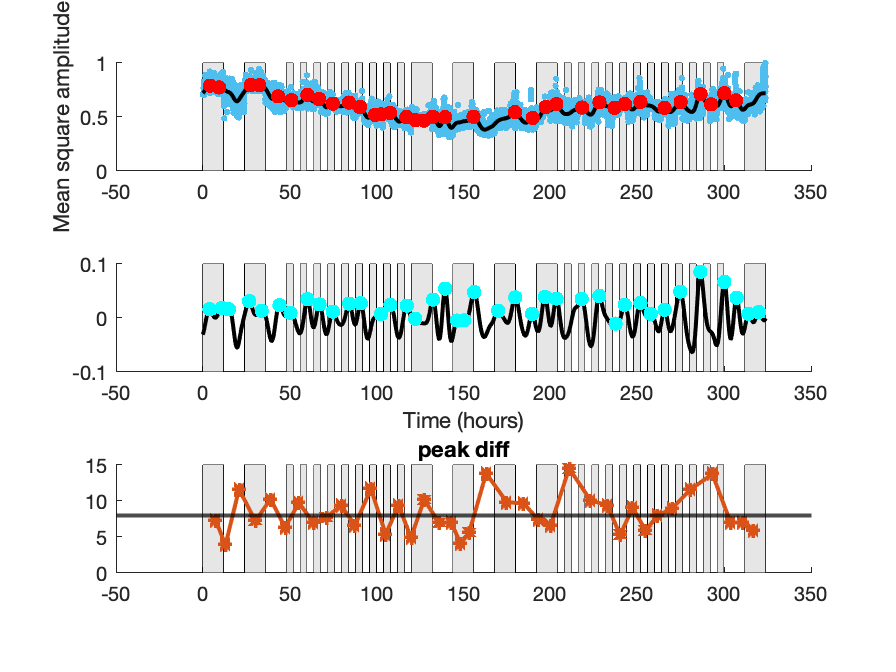

k_prettypeakplotter(l24kg(64), 1);

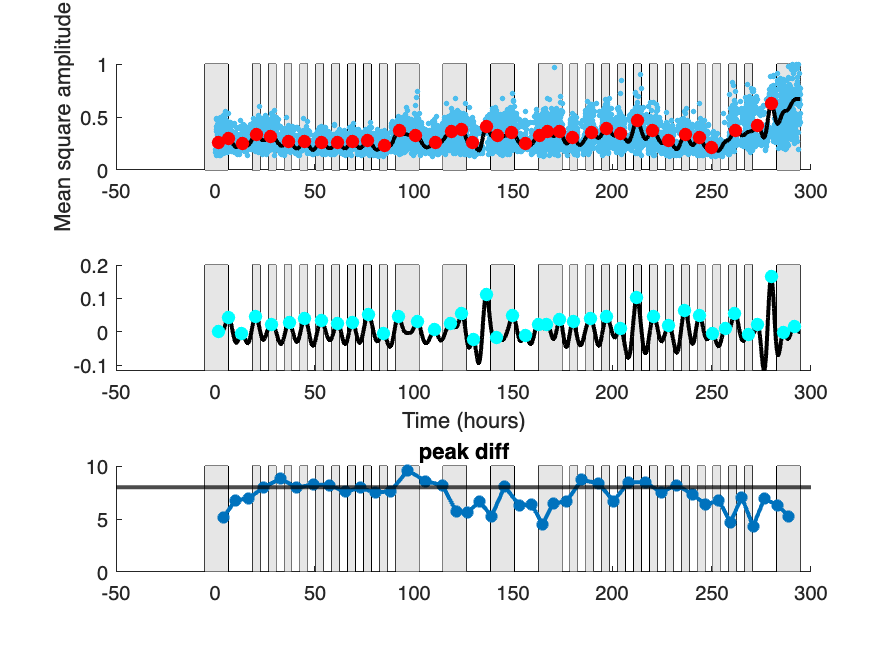

k_prettypeakplotter(l24kg(65), 1);

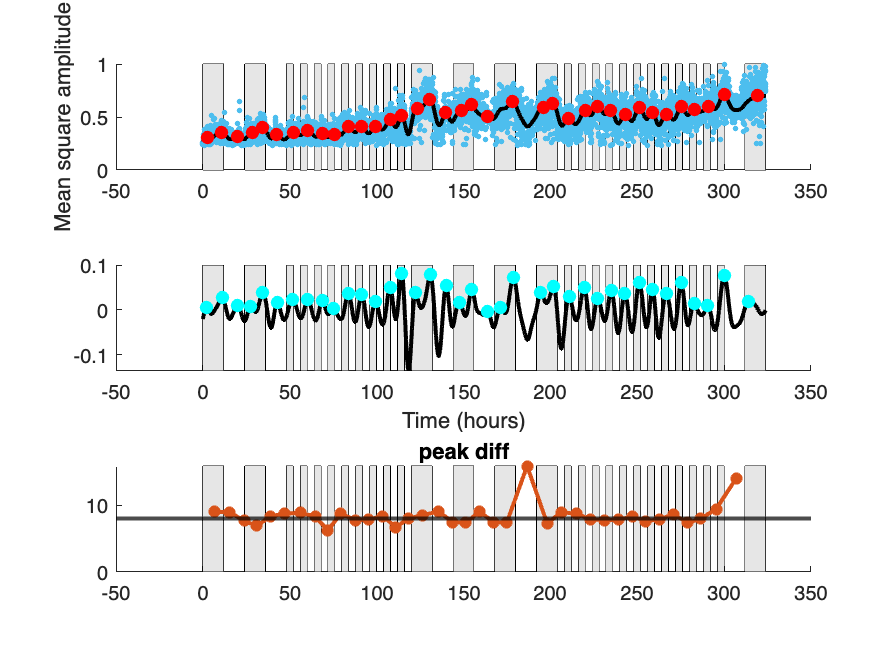

k_prettypeakplotter(l24kg(66), 1);

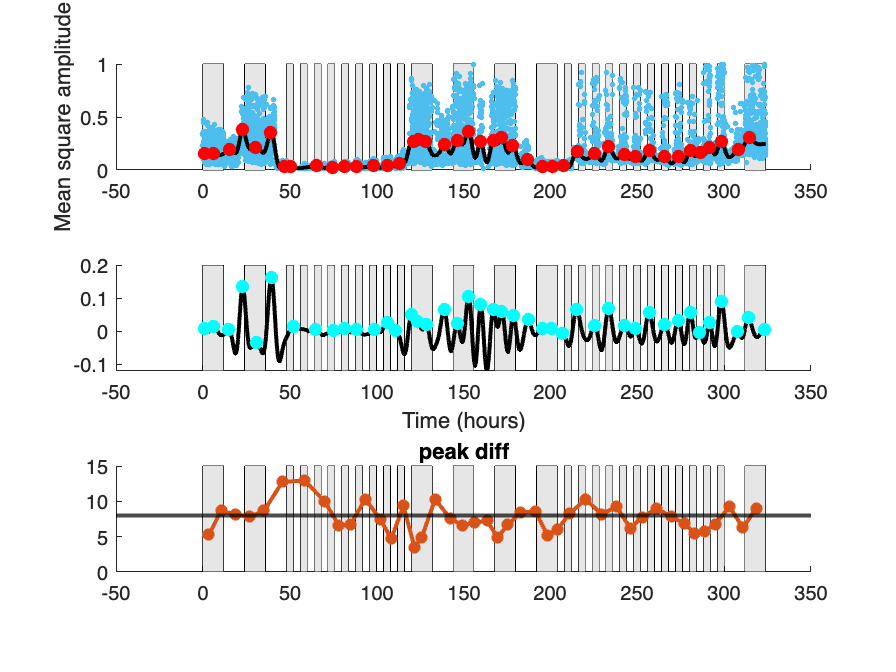

k_prettypeakplotter(l24kg(67), 1);

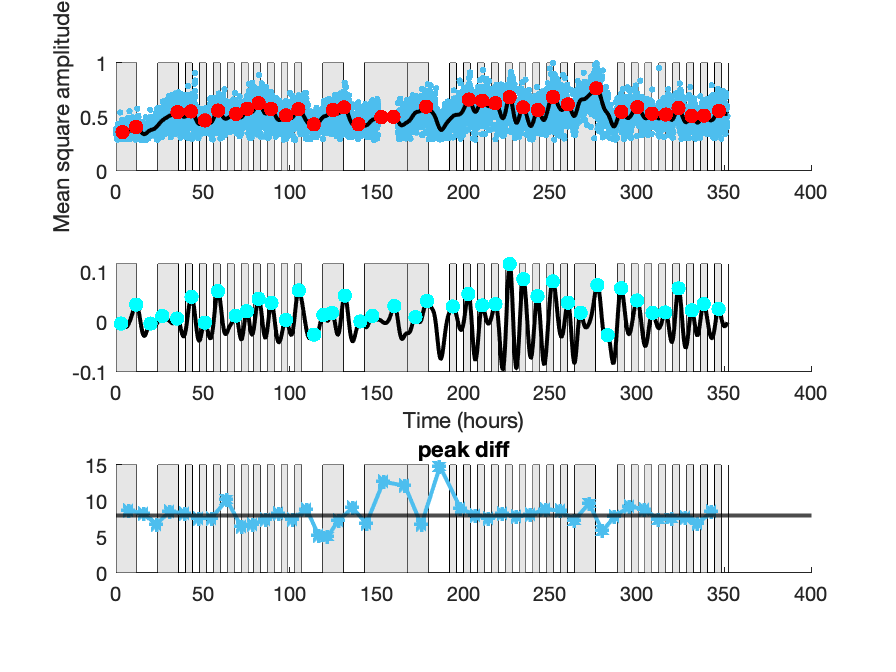

k_prettypeakplotter(l24kg(68), 1); 

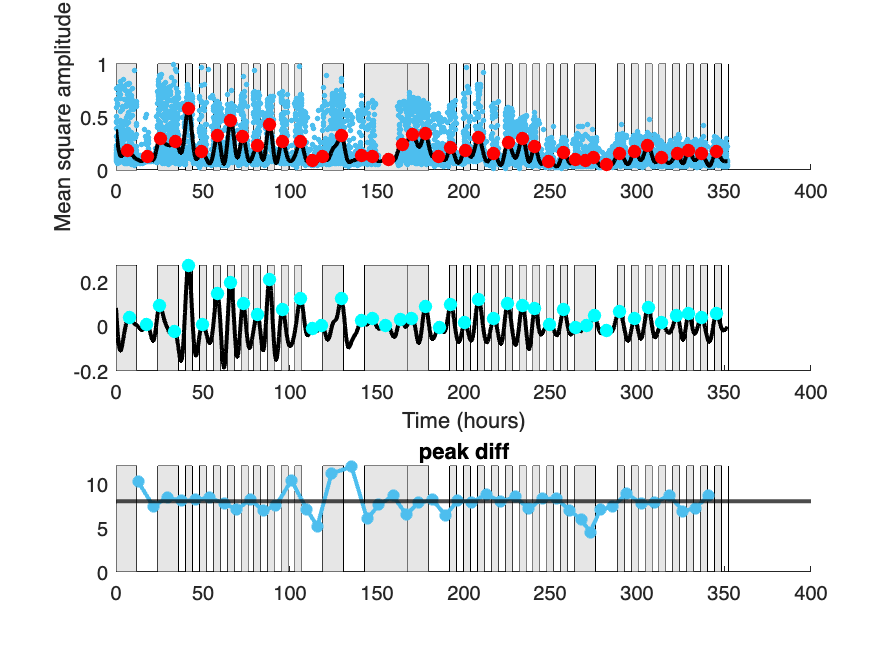

k_prettypeakplotter(l24kg(69), 1); 

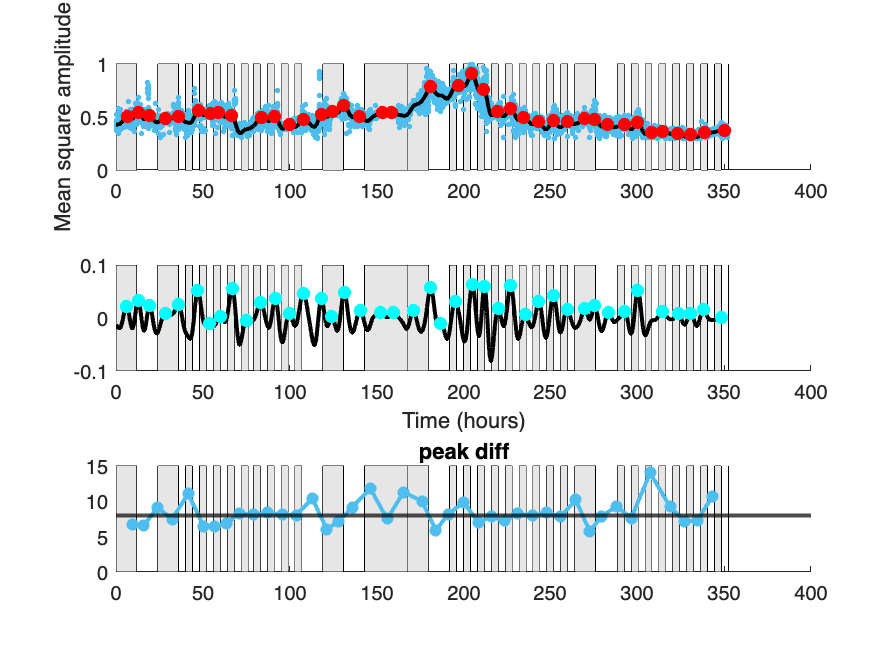

k_prettypeakplotter(l24kg(70), 1); 

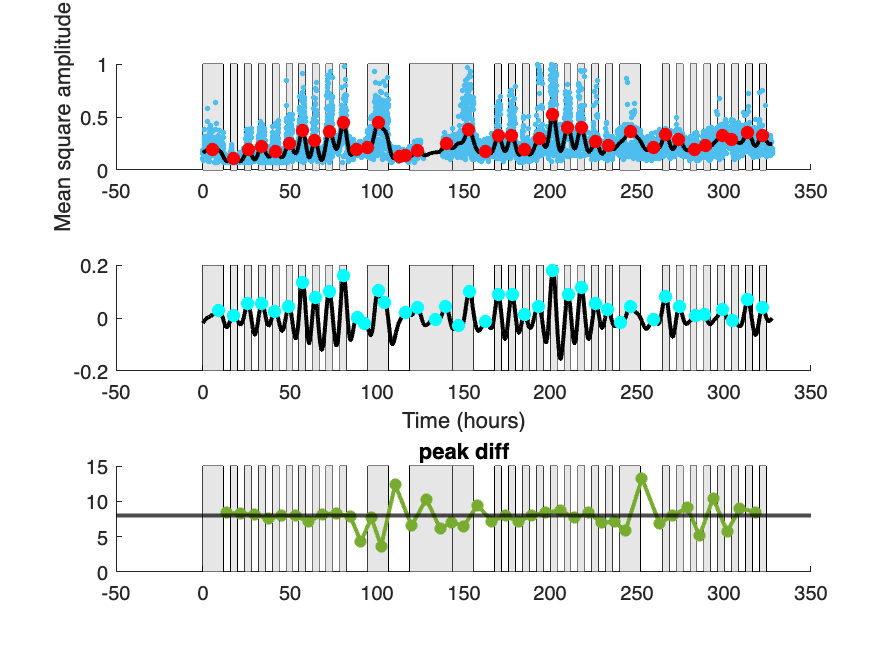

k_prettypeakplotter(l24kg(71), 1); 

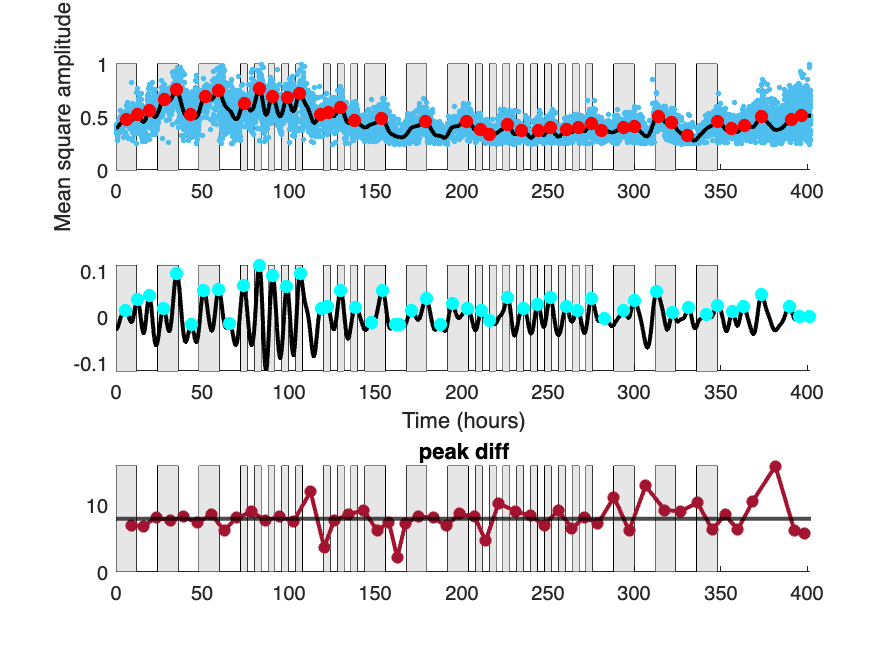

k_prettypeakplotter(l24kg(72), 1); 

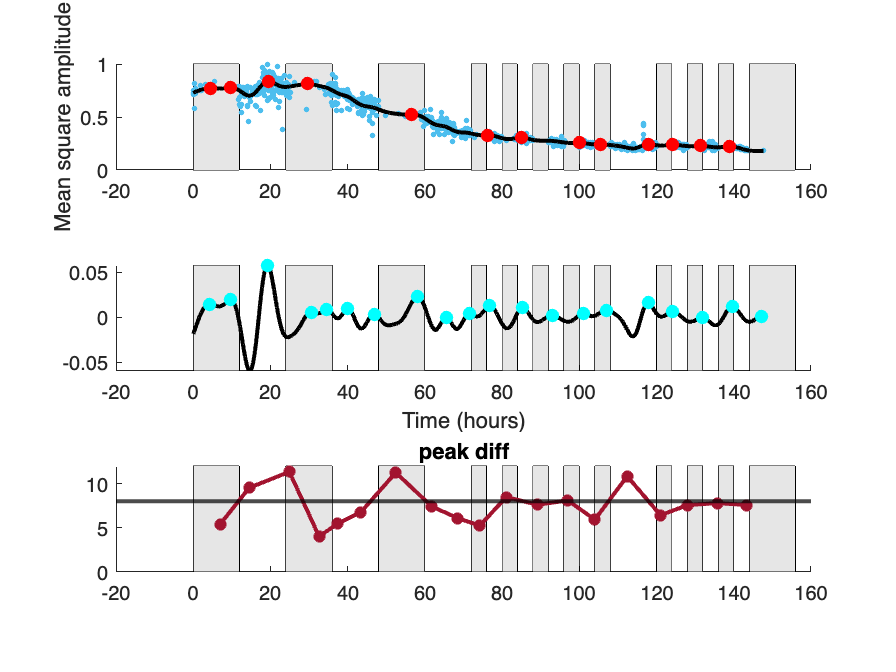

k_prettypeakplotter(l24kg(73), 1); 

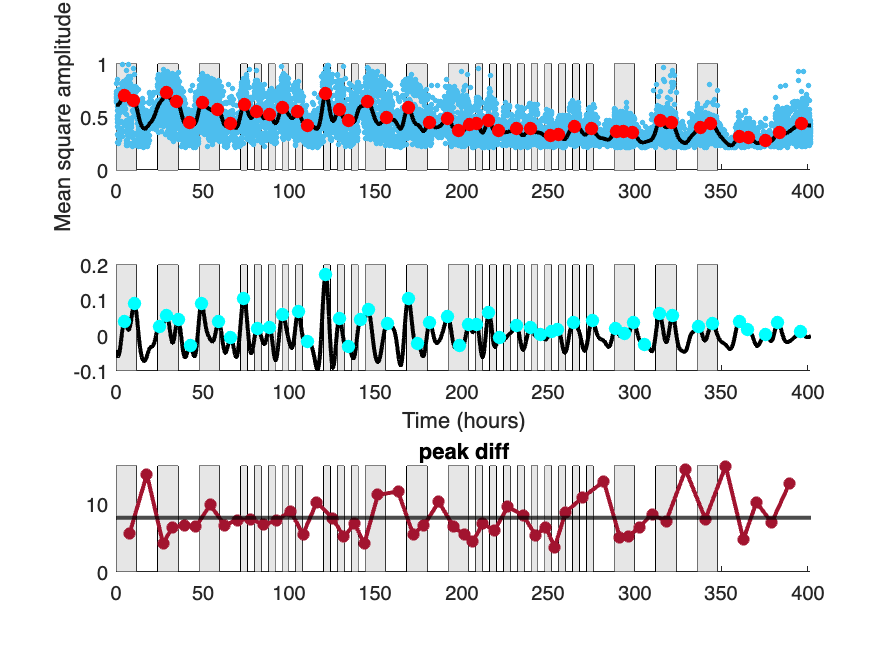

k_prettypeakplotter(l24kg(74), 1); 

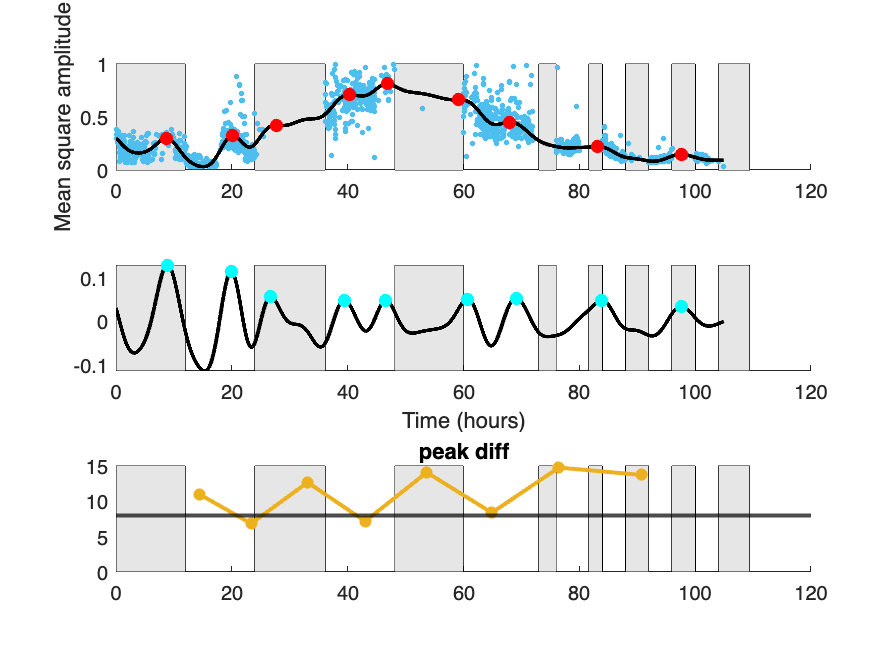

k_prettypeakplotter(l24kg(75), 1); 

## edits

#### trim data

tempdata = KatieTrimmer(l24kg(k).e);

if before was on purpose. extra step in case of clicking regret

l24kg(k).e = tempdata;

#### frequency trimming

tempdata = KatieFreakyFreqRemover(l24kg(k).e);

l24kg(k).e = tempdata;

##  plot 

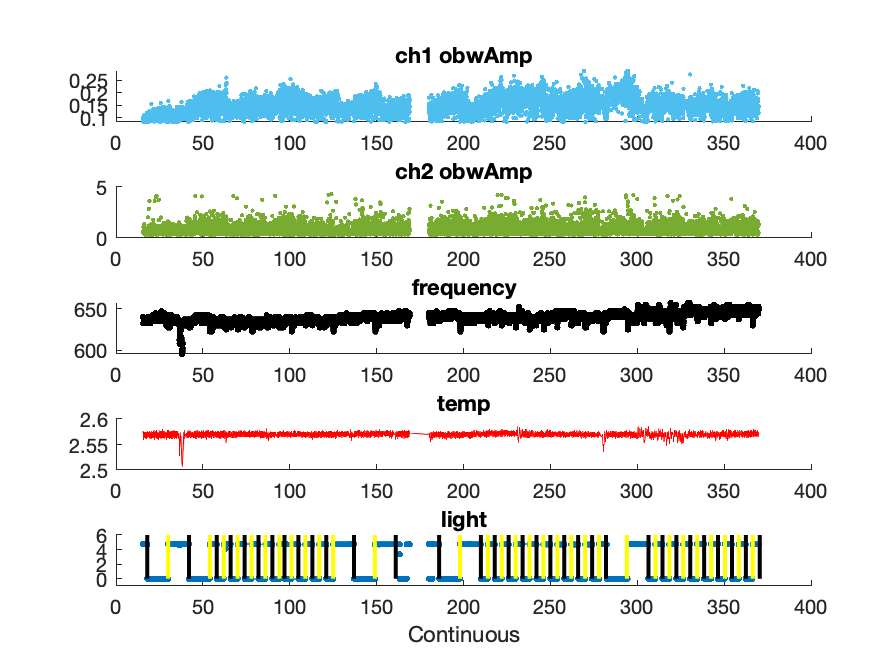

k_initialplotter(l24kg(k));

#### Remove outliers

Must be redone after trimming

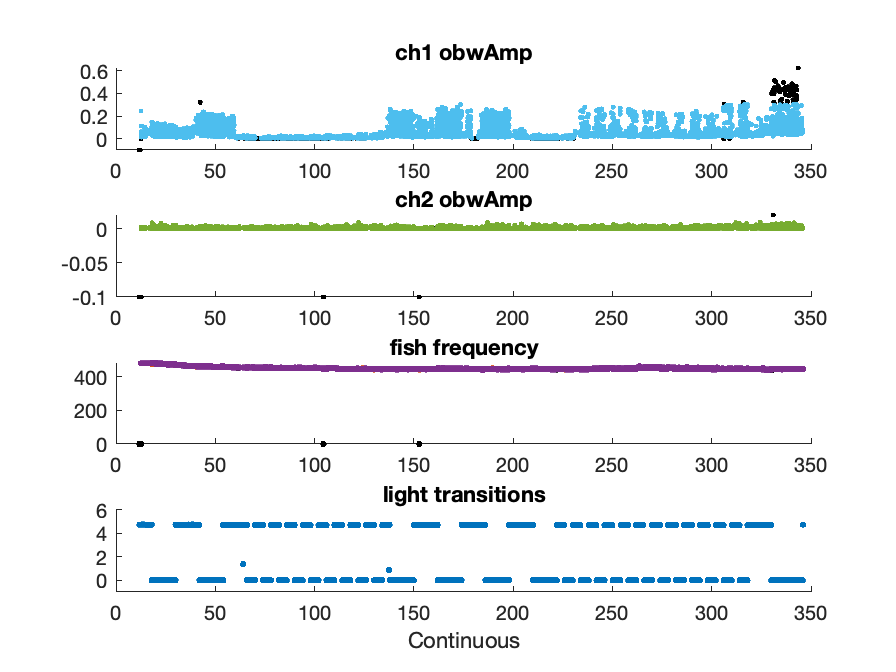

l24kg(k).idx = KatieRemover(l24kg(k).e);
k_removedsingleplotter(l24kg(k));

l24kg(k).idx = KatieReplacer(l24kg(k), 1);

Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminatin

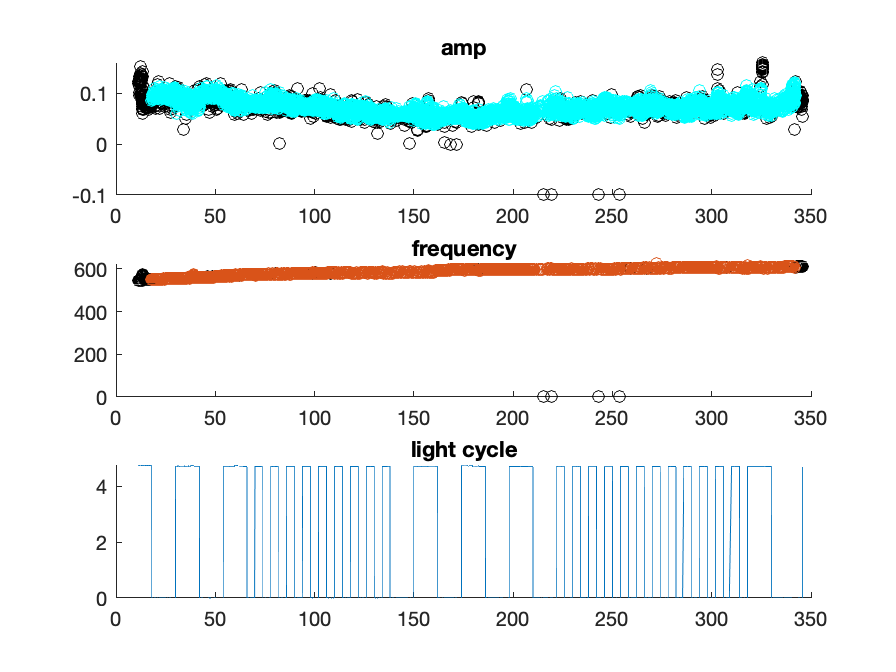

k_replacercheckplotsingle(l24kg(k), 1); 

##  plot again

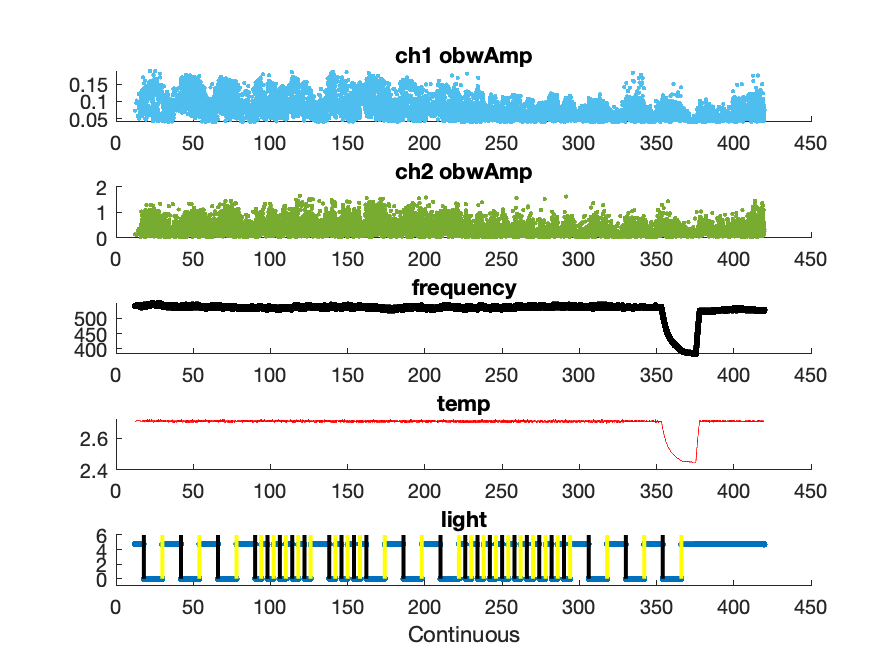

k_initialplotter(l24kg(k));

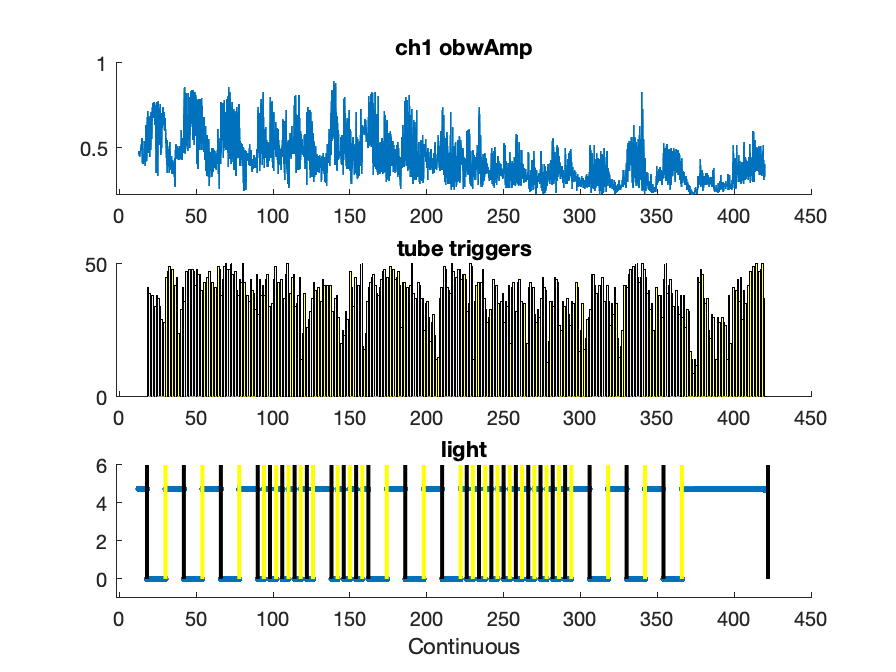

k_ampbinplotter(l24kg(k));

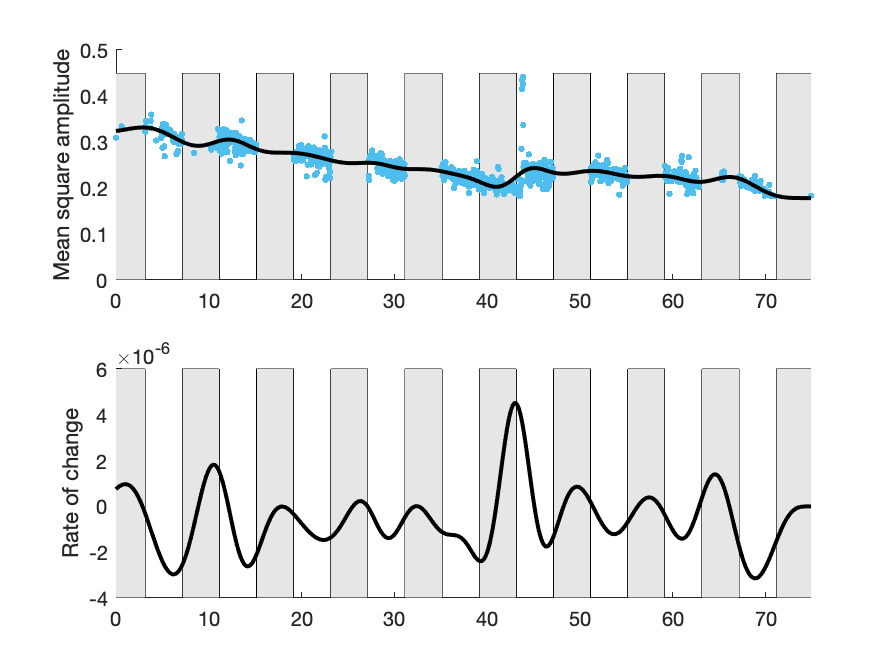

k_prettyampplotter(l24kg(k), 1);

 k_prettypeakplotter(l24kg(k), 1);

## label

l24kg(k).info = KatieTempLabeler(l24kg(k).e);

l24kg(k).info.luz = k_singlemanuallightlabeler(l24kg(k));

lidx = find(abs(l24kg(k).info.luz)< 91);
first12 = l24kg(k).info.luz(lidx);

lidx = find(abs(l24kg(k).info.luz)> 125 & abs(l24kg(k).info.luz)< 138);
second12 = l24kg(k).info.luz(lidx);
% 
% lidx = find(abs(l24kg(k).info.luz)> 293 & abs(l24kg(k).info.luz)< 367);
% third12 = l24kg(k).info.luz(lidx);



lidx = find(abs(l24kg(k).info.luz)> 90 & abs(l24kg(k).info.luz)< 127);
first4 = l24kg(k).info.luz(lidx);

lidx = find(abs(l24kg(k).info.luz)> 137 & abs(l24kg(k).info.luz)< 163);
second4 = l24kg(k).info.luz(lidx);

% lidx = find(abs(l24kg(k).info.luz)> 221 & abs(l24kg(k).info.luz)< 294);
% third4 = l24kg(k).info.luz(lidx);



lidx = find(abs(l24kg(k).info.luz)> 13 & abs(l24kg(k).info.luz)< 150);
part1 = l24kg(k).info.luz(lidx);

lidx = find(abs(l24kg(k).info.luz)> 150);
part2 = -l24kg(k).info.luz(lidx);

l24kg(k).info.luz = [part1  part2];

% lidx = find(abs(l24kg(k).info.luz)> 96 & abs(l24kg(k).info.luz) <126);
% third4 = l24kg(k).info.luz(lidx);

l24kg(k).info.luz = [first12, first4, second12, second4, 174];


templuz = (abs([l24kg(k).info.luz]))-24;
templuz3 = unique(templuz);

for j = 1:length(templuz3)
    if mod(j,2) == 1
        templuz2(j,:) = -templuz3(j);
    else
        templuz2(j,:) = templuz3(j);
    end
end
l24kg(k).info.luz = templuz2';



lidx = find(abs(l24kg(k).info.luz)< 400);
l24kg(k).info.luz = l24kg(k).info.luz(lidx);

[~, sortidx] = sort(abs(l24kg(k).info.luz));
l24kg(k).info.luz = l24kg(k).info.luz(sortidx);

channel = 1;
    xidx = find([l24kg(k).e(channel).s.timcont]/3600 >26.42 & [l24kg(k).e(channel).s.timcont]/3600 < 33);
    for j = 1:length(xidx)
    l24kg(k).e(channel).s(xidx(j)).obwAmp = l24kg(k).e(channel).s(xidx(j)).obwAmp*6;
    end
